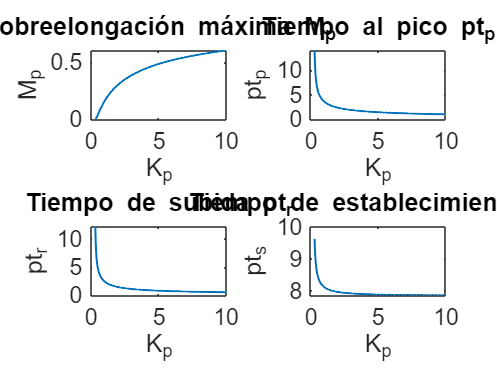

close all;    % Cierra todas las figuras abiertas
clear;        % Borra todas las variables del workspace
clc;          % Limpia la ventana de comandos

% Parámetros fijos
K = 1;
p = 1;
nu = 0.02;

% Rango de Kp
Kp = linspace(0.3, 10, 300);  % Evitamos valores donde 4*K*Kp - p^2 <= 0
Delta = sqrt(4*K*Kp - p^2);   % Asegura sistema subamortiguado

% Cálculos
Mp_vals = exp(-(pi * p) ./ Delta);
ptp_vals = 2*pi ./ Delta;
phi = acos(p ./ (2 * sqrt(K * Kp)));
ptr_vals = 2*(pi - phi) ./ Delta;
pts_vals = log((2 * sqrt(K * Kp)) ./ (nu * Delta))*2;

subplot(2,2,1);
plot(Kp, Mp_vals, 'LineWidth', 1.5);
title('Sobreelongación máxima M_p', 'FontSize', 17);
xlabel('K_p', 'FontSize', 17);
ylabel('M_p', 'FontSize', 17);
set(gca, 'FontSize', 17);

subplot(2,2,2);
plot(Kp, ptp_vals, 'LineWidth', 1.5);
title('Tiempo al pico pt_p', 'FontSize', 17);
xlabel('K_p', 'FontSize', 17);
ylabel('pt_p', 'FontSize', 17);
set(gca, 'FontSize', 17);

subplot(2,2,3);
plot(Kp, ptr_vals, 'LineWidth', 1.5);
title('Tiempo de subida pt_r', 'FontSize',17);
xlabel('K_p', 'FontSize', 17);
ylabel('pt_r', 'FontSize', 17);
set(gca, 'FontSize', 17);

subplot(2,2,4);
plot(Kp, pts_vals, 'LineWidth', 1.5);
title('Tiempo de establecimiento pt_s', 'FontSize', 17);
xlabel('K_p', 'FontSize', 17);
ylabel('pt_s', 'FontSize', 17);
set(gca, 'FontSize', 17);

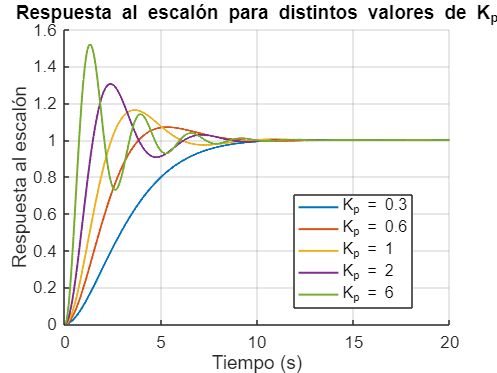


clear;        % Borra todas las variables del workspace
clc;          % Limpia la ventana de comandos

% Parámetros del sistema
K = 1;      % Ganancia fija
p = 1;      % Parámetro del sistema
Kp_vals = [0.3, 0.6, 1, 2, 6];  % Valores de K_p a evaluar
t = 0:0.01:20;  % Tiempo de simulación

% Crear figura
figure;
hold on;

for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    
    % Función de transferencia: H_P(s) = (Kp*K)/(s^2 + p*s + Kp*K)
    num = Kp * K;
    den = [1, p, Kp * K];
    
    sys = tf(num, den);
    [y, t_out] = step(sys, t);
    
    plot(t_out, y, 'LineWidth', 1.5, 'DisplayName', ['K_p = ' num2str(Kp)]);
end

xlabel('Tiempo (s)', 'FontSize', 13);
ylabel('Respuesta al escalón', 'FontSize', 13);
title('Respuesta al escalón para distintos valores de K_p', 'FontSize', 13);
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 13);